# **Script illustrating how to generate an OI with no blur  **

*This tutorial generates an OI object that has delta function PSFs for all wavelengths*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2022*

# **Step 1.** Generate the PSF stack

Here, we specify the spatial and spectral sampling, as well as the pupil size and the retinal magnification factor (in microns/deg)

nSamplesHalf = 200;
sampleSizeArcMin = 0.01;
spatialSupportArcMin = (-nSamplesHalf:nSamplesHalf)* sampleSizeArcMin;
wavelengthSupport = 400:10:700;

% Pupil size
pupilDiameterMM = 3.0;

% Retinal magnification factor
umPerDegree = 280;

% Generate the delta-function PSF stack
thePSFstack = zeros(2*nSamplesHalf+1, 2*nSamplesHalf+1, numel(wavelengthSupport));
thePSFstack(1+nSamplesHalf, 1+nSamplesHalf,:) = 1.0;

# **Step 2.** Generate the no-blur OI from the PSF stack

% Generate the custom OI    
theNoBlurOI = oiFromPSF(thePSFstack, wavelengthSupport, ...
     spatialSupportArcMin, pupilDiameterMM, umPerDegree);

% Also generate the default OI (for comparison)
theDefaultOI = oiCreate();


# **Step 3.** Generate a test scene

sceneFOVdegs = 2*max(spatialSupportArcMin)/60;
theTestScene = sceneCreate('point array', 32);
theTestScene  = sceneSet(theTestScene, 'fov', sceneFOVdegs);
theTestScene  = sceneSet(theTestScene, 'distance', 1.0);

# **Step 4.** Compute the optical image of the test scene under the custom and default optics

theNoBlurOpticalImage = oiCompute(theTestScene, theNoBlurOI);
theDefaultOpticalImage = oiCompute(theTestScene, theDefaultOI);

# **Step 5.** Visualize the test scene and the two optical images

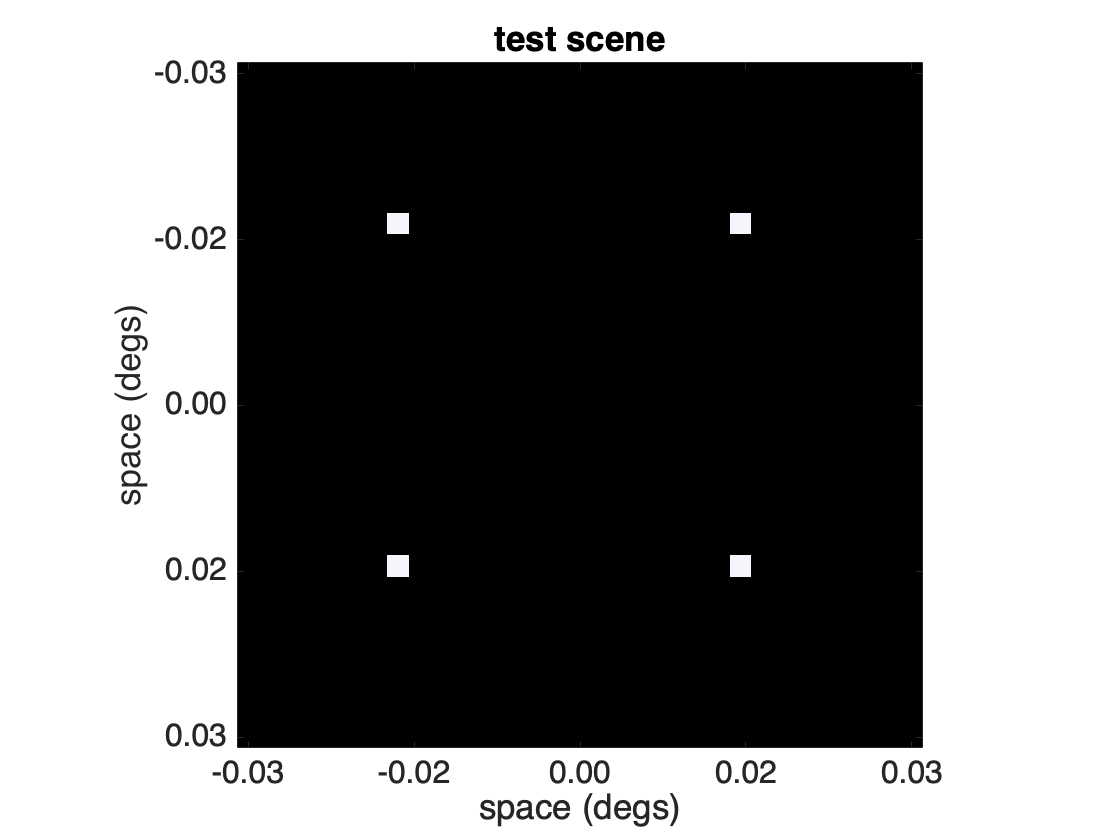

visualizeScene(theTestScene, ...
        'spatialSupportInDegs', true, ...
        'crossHairsAtOrigin', true, ...
        'displayRadianceMaps', false ...
        );
set(gca, 'XLim', sceneFOVdegs/2*[-1 1], 'YLim', sceneFOVdegs/2*[-1 1]);
title('test scene');

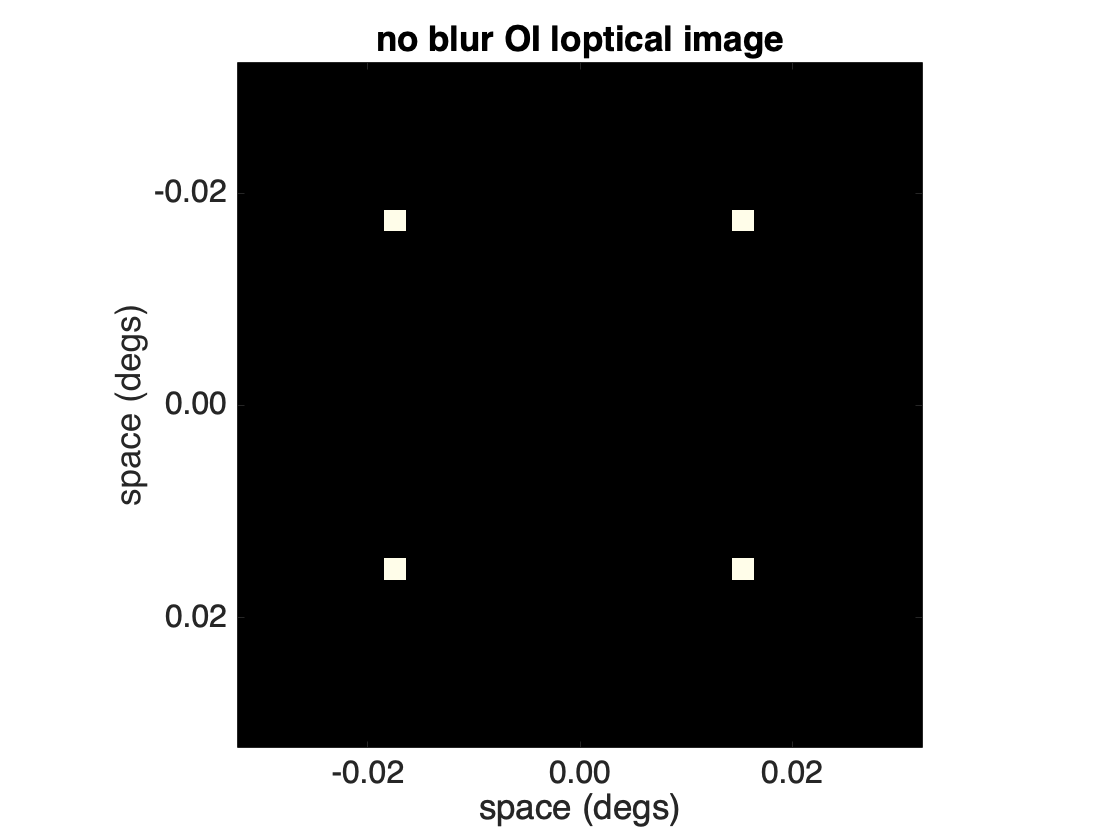


visualizeOpticalImage(theNoBlurOpticalImage,...
        'displayRadianceMaps', false);
set(gca, 'XLim', sceneFOVdegs/2*[-1 1], 'YLim', sceneFOVdegs/2*[-1 1]);
title('no blur OI loptical image');

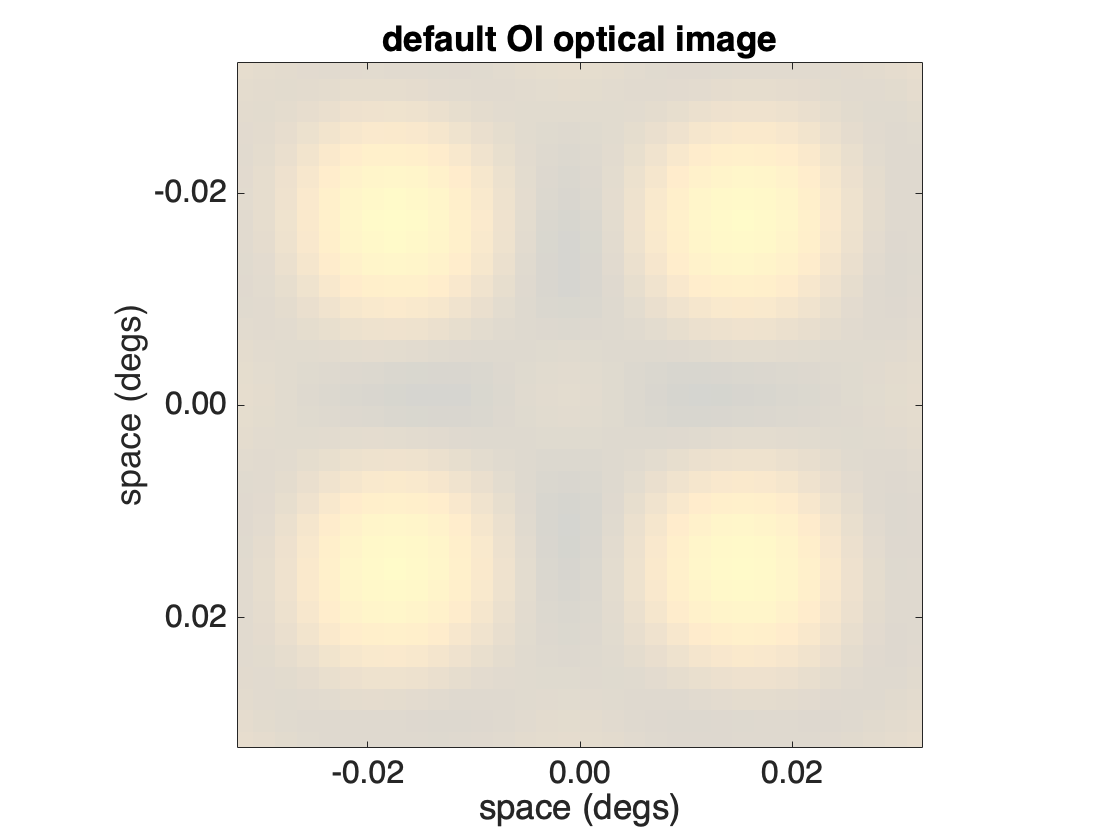


visualizeOpticalImage(theDefaultOpticalImage,...
        'displayRadianceMaps', false);
set(gca, 'XLim', sceneFOVdegs/2*[-1 1], 'YLim', sceneFOVdegs/2*[-1 1]);
title('default OI optical image')

# **Step 6.** Visualize the  two PSFS

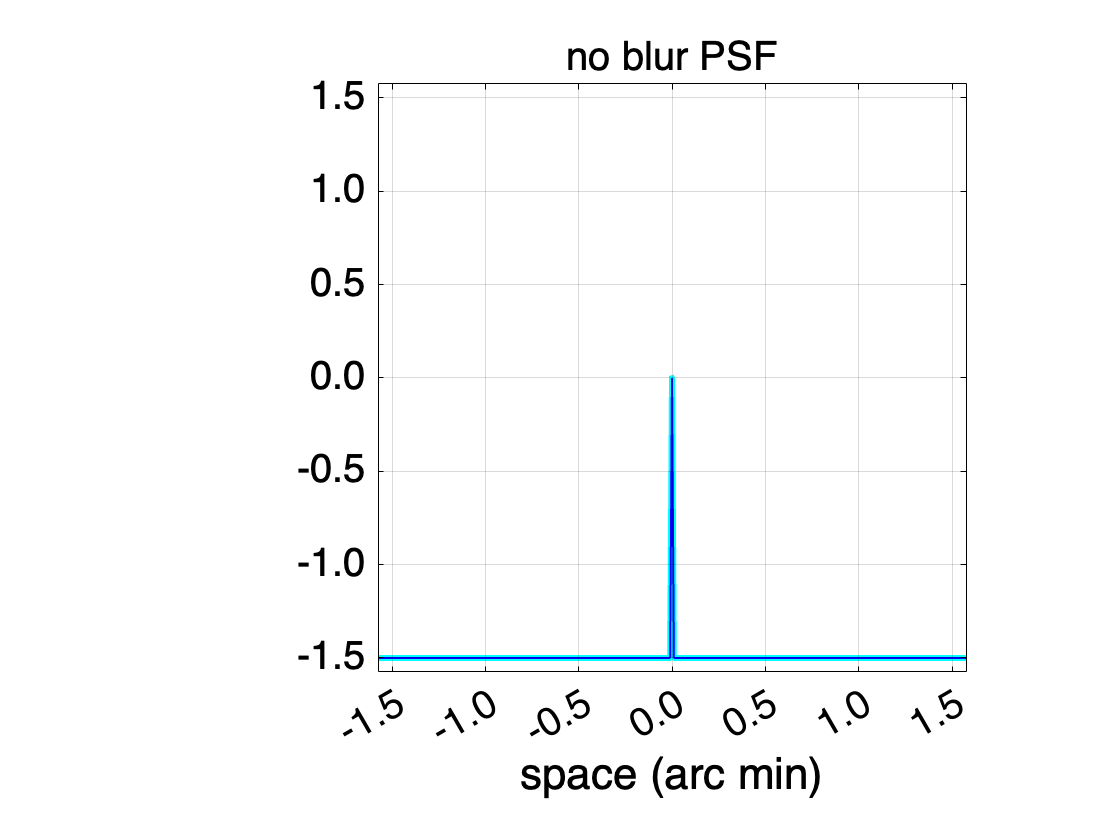

visualizePSF(theNoBlurOI, 550, 3)
title('no blur PSF')

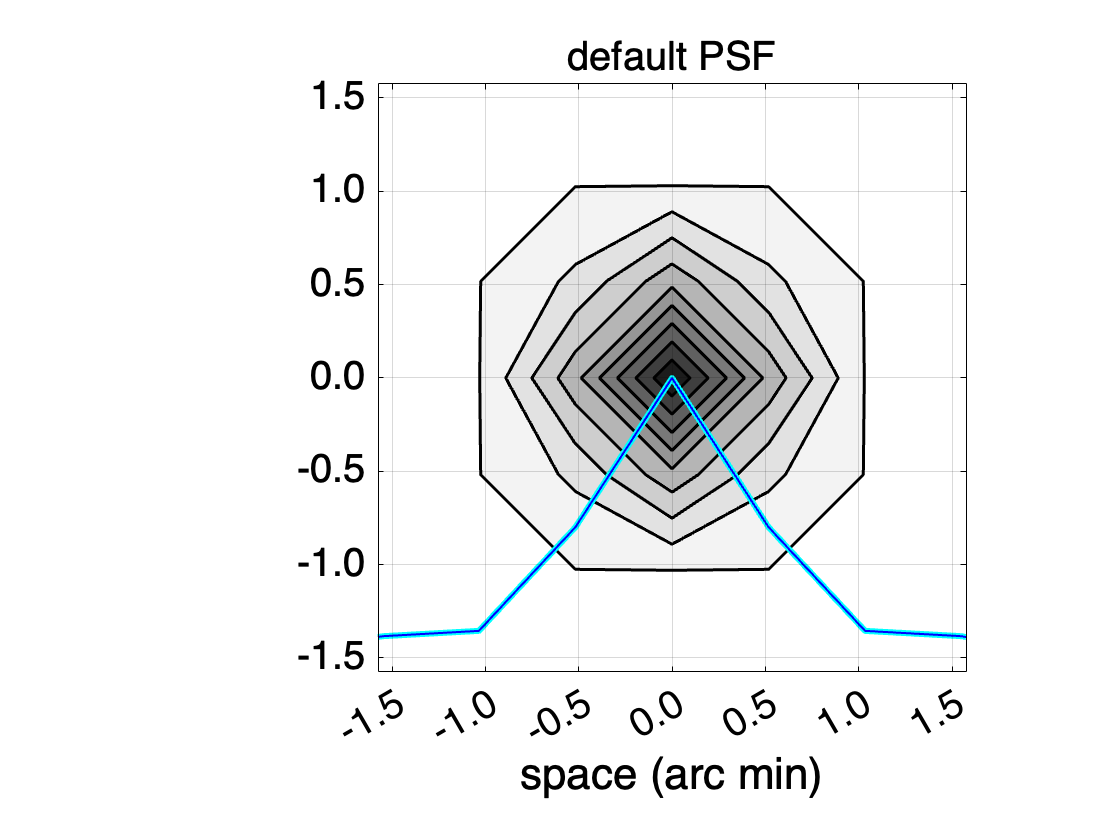

visualizePSF(theDefaultOI, 550, 3)
title('default PSF')